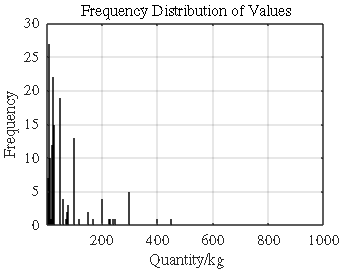

clear; clc;

% Load and clean data
data = [1000	1000	450	400	300	300	300	300	300	250	240	228.85	225	200	200	200	200	169.58	150	150	120	100	100	100	100	100	100	100	100	100	100	100	100	100	80	80	80	75	75	70	60	60	60	60	50.01	50	50	50	50	50	50	50	50	50	50	50	50	50	50	50	50	50	50	50	30	30	30	30	30	30	30	30	30	30	30	30	30	30	30	29.5	28.9	25	25	25	25	25	25	25	25	25	25	25	25	25	25	25	25	25	25	25	25	25	25	20	20	20	20	20	20	20	20	20	20	20	20	17	16.29	15	15	15	15	15	15	15	15	15	15	14	14	14	13.55	13	12	12	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	10	9.2	7	6	5	5	5	5	5	5	5	4.5	4	3.2	1.7	1.32	1.3	1	1	1	1	1	1	1	1	1	1	1	0.9	0.9	0.8	0.65	0.6	0.55	0.5	0.5	0.5	0.45	0.4	0.4	0.4	0.4	0.3	0.3	0.25	0.2	0.19	0.19	0.1002	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1	0.1];
data = data(data > 1);  % Filter out non-positive numbers

% Frequency Bar Chart (Beautified)
figure('Color', 'w'); % white background
vals = unique(data);
counts = histc(data, vals);

bar(vals, counts, 'FaceColor', [0.2, 0.6, 0.8], 'EdgeColor', 'k');
xlabel('Quantity/kg', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Frequency', 'FontSize', 12, 'FontWeight', 'bold');
title('Frequency Distribution of Values', 'FontSize', 14, 'FontWeight', 'bold');
grid on;
set(gca, 'FontSize', 11);

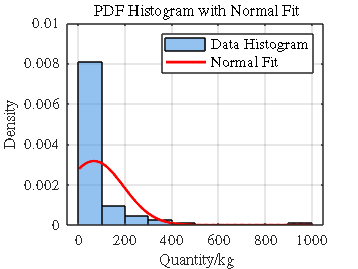


% Normalized Histogram + Normal Fit (Beautified)
figure('Color', 'w');
histogram(data, 'Normalization', 'pdf', ...
    'FaceColor', [0.3 0.6 0.9], ...
    'EdgeColor', 'k', ...
    'FaceAlpha', 0.6);
hold on;

mu = mean(data);
sigma = std(data);
x = linspace(min(data), max(data), 500);
y = normpdf(x, mu, sigma);

plot(x, y, 'r-', 'LineWidth', 2);
xlabel('Quantity/kg', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Density', 'FontSize', 12, 'FontWeight', 'bold');
title('PDF Histogram with Normal Fit', 'FontSize', 14, 'FontWeight', 'bold');
legend({'Data Histogram', 'Normal Fit'}, 'FontSize', 11, 'Location', 'northeast');
grid on;
set(gca, 'FontSize', 11);